# Assignment 3

## Task 1

### Outlier detection

In this part, extremly long retention times should be detected and removed from data as these are outliers.

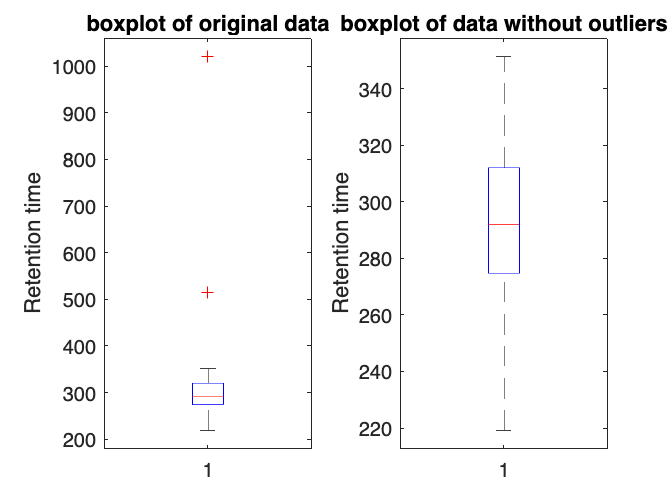

clear

load('assignment_data.mat');

retention_times = [seconds(retentionTimes.retentionTime)]; % change datetime to values

figure;
subplot(1,2,1);
boxplot(retention_times) % plotting a boxplot to get an imperssion of the outliers
ylabel('Retention time');
title('boxplot of original data');

% Define threshold using Tukey's Rule

Q1 = prctile(retention_times, 25);
Q3 = prctile(retention_times, 75);
IQR = Q3 - Q1;

k = 1.5;  % This value is used as it is very common. Other than online sources that recommend using this value, there is no further reason (no, not chatGPT but several other websites) 
threshold = k * IQR;

outliers = find(retention_times < Q1 - threshold | retention_times > Q3 + threshold); % a list of outliers is created.

filtered_rt = retention_times; % new list with the exact same data is created
filtered_rt(outliers) = []; % the new list compares all values with the outliers and removes those

subplot(1,2,2)
boxplot(filtered_rt) % boxplot of filtered data to see how the removed outliers effect the data
title('boxplot of data without outliers')
ylabel('Retention time');

The calculation of the threshold was researched online, also with help of chatGPT and follow up research about the answers of chatGPT. After some consideration, the Tukey's Rule for the threshold calculation was used. The value of k was set to 1.5 as it is a very common used value which was used by chatGPT and varyfied by various other websites. 

A new list called outliers was created were all the outliers were added to. Another list called filtered_rt was created with the exact same values as the original data. However, this new list was compared to the outliers list and evey value that was the same in both lists got removed from the filtered_rt list.

The two boxplots were created to check if the outlier removal was successful. 

### Check if normal distribution

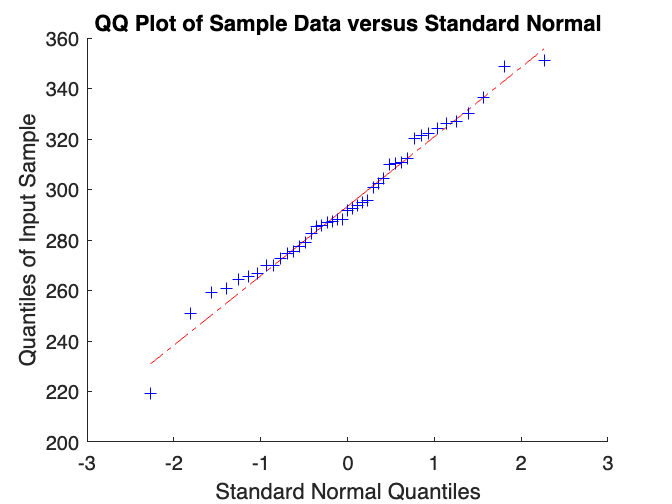

% visual inspection with qqplot
figure;
qqplot(filtered_rt);

The qqplot function creates a function that gives back visiual information about wether a data set follows normal distribution or not. If the data points follow the red line, like in this case, the data is normal distributed. 

### Confidence interval

In this section, a confidence interval of 95% for the normal distributed data should be created. 

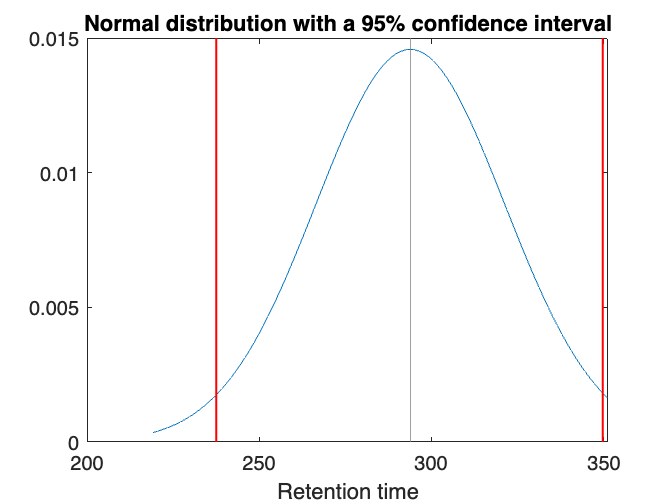

sigma = std(filtered_rt);
mu = mean(filtered_rt);
P_upper = prctile(filtered_rt, 97.5);
P_lower = prctile(filtered_rt, 2.5);

x = linspace(min(filtered_rt), max(filtered_rt)); % it is possible to add e.g. 30 values to the min and max to get a normal distribution that is not cut off

pdf_values = normpdf(x, mu, sigma);
plot(x, pdf_values);
hold on
plot([P_lower, P_lower], [0, 0.015], 'r', LineWidth=1);
plot([P_upper, P_upper], [0, 0.015], 'r', LineWidth=1);
plot([mu, mu], [0, 0.015], 'Color', [0.5, 0.5, 0.5], LineWidth=0.5);
title('Normal distribution with a 95% confidence interval')
xlabel('Retention time')
hold off

The standard deviation and the mean value of the filtered data (data without outliers)  was calculated. P_upper and P_lower define the thresholds for the confidence interval. These P values are caluclated with the prctile function to retrieve the 97.5 percentile and the 2.5 percentile. The 2.5% are conisdered at the upper and the lower threshold of the confidence interval to have a 95% confidence interval. This means, a value has a 95% chance to be within the two red lines that can be seen in the graph.

For the plot, the function normpdf was used which creates a normal distribution with the given values x.  The function linspace creates the data set x by taking the minimal and the maximum value of the filtered data set and distributing values between those two numbers. The threshold were added afterwards.

## Task 2

### Which of the time series shows the most steady volume flow according to the V10/V90 criterion?


ts_array = {ts1, ts2, ts3};

for n=1:numel(ts_array)

    relative_IQR = quantile(ts_array{n}, 0.1)/quantile(ts_array{n}, 0.9);
    fprintf('The relative IQR of ts%d is %d\n', n, relative_IQR)

end

The relative IQR of ts1 is 6.877877e-01
The relative IQR of ts2 is 1.145925e-01
The relative IQR of ts3 is 2.759662e-01


The relative IQR is calculated by deviding quantile 10 with quantile 90. The closer the result is to the number 1, the steadier the colume flow is. According to the results of these calulations, the ts1 has the steadiest volume flow of all 3 data sets.

The calculations were put in a for loop. For this, all data sets were put into an array in order to loop through it. All the results are printed at the end.

### What share of time was the volume flow above 1.5 times of the average volume flow for each time series?


for n=1:numel(ts_array)
    
    time_share = crit_time(ts_array{n});
    fprintf('The time share of ts%d that exceeds the set threshold is %d\n', n, time_share);

end

The time share of ts1 that exceeds the set threshold is 2.000100e-02
The time share of ts2 that exceeds the set threshold is 2.487000e+01
The time share of ts3 that exceeds the set threshold is 1.625000e+01


First, a function for the caluclation of the time share was programmed. This was done to make the code itself shorter in order to get a better overview. The function first calculates a threshold (1.5 * mean) and compares then the values of the data with the threshold. Every data point that exceeds the threshold is put into a list. Since every data point represents one second, the time amount can be calulated with the sum of the list. Therefore, the size of the threshold list devided by the size of the original data set mulitplied by 100 give the percentage of time that is avbove the threshold. According to these calculations, ts2 had the highest time, in which the flow was above the given threshold.

### Analyse the three time series using the tools from the lecture

#### a) The series are all random processes or random walks.

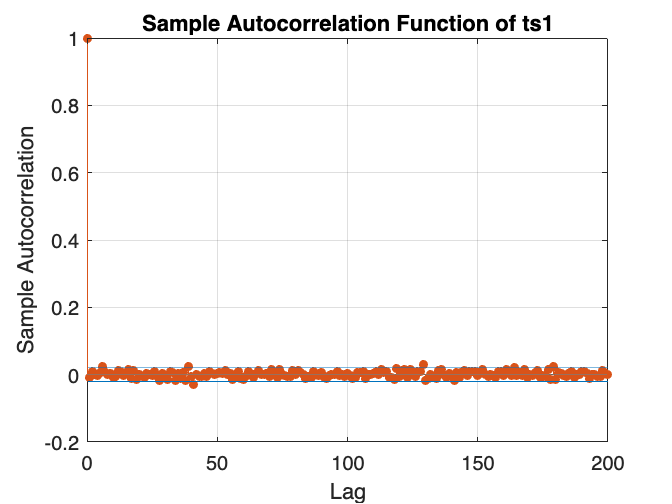

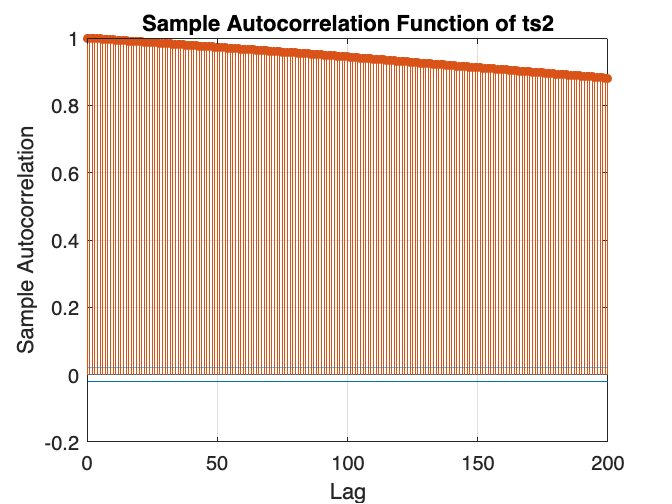

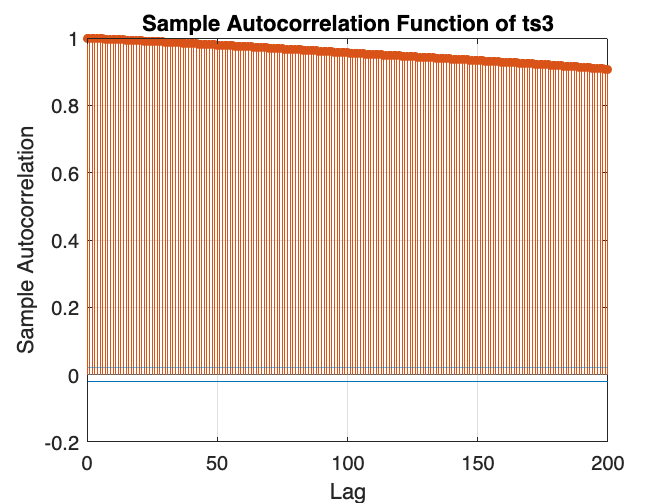

for n=1:numel(ts_array)
    figure;
    autocorr(ts_array{n}, NumLags=200) % value 200 can be changed to other values, it defines how many Lags are used.
    title(append('Sample Autocorrelation Function of ts', string(n)))
    
end

The autocorr function creates an autocorrelation function with which the data sets can be analysed. The function gives information wether the data is a random process or a random walk. In this case, the ts1 is a random process and ts2 and ts3 are random walks.

#### b) Which distribution does the random component of each time series follow?

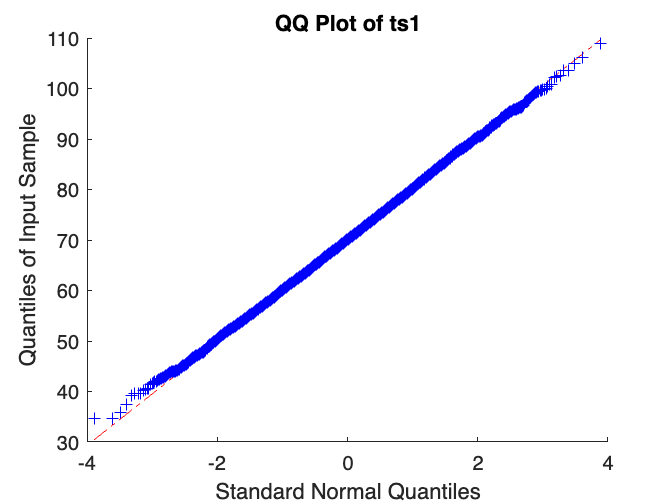

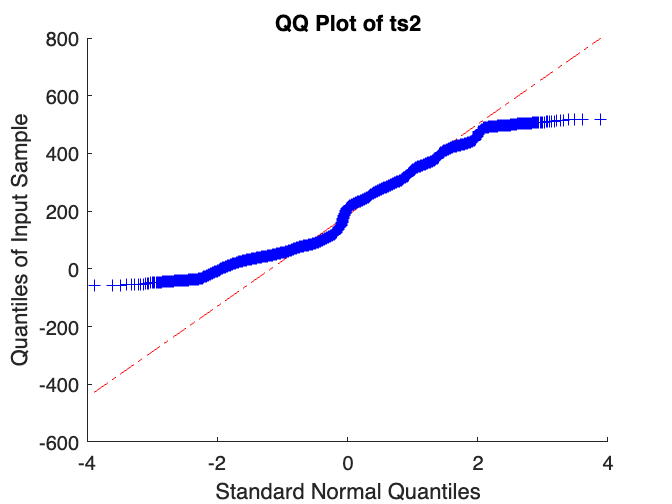

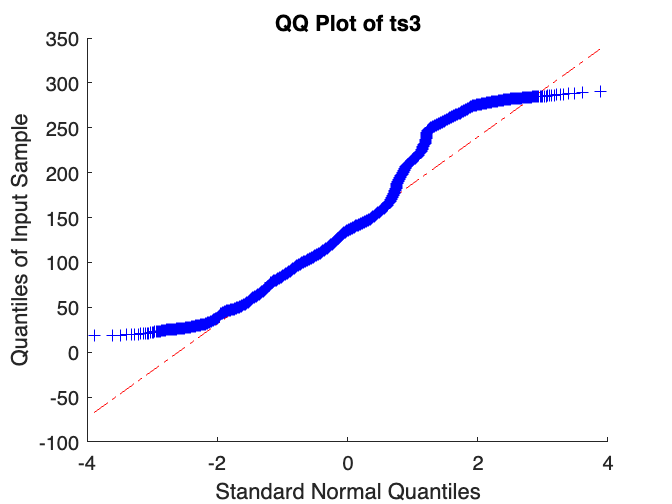

for n=1:numel(ts_array)

    figure;
    qqplot(ts_array{n});
    title(append('QQ Plot of ts', string(n)))

end

With the qqplot function, a plot is created. With this plot, it is easy to determine wether the data follows a normal distribution or not. In this case, ts1 follows a normal distribution as the values are all close to the red line. ts2 and ts3 are not normal distributed.

## Functions

function result = crit_time(data)
        
    data_mean = mean(data); % calculating the eman of the data 
    crit_flow = 1.5 * data_mean; % 1.5 the mean is the set threshold
    above_thres = data(data > crit_flow); % comparing the data with the set threshold and putting it in a list
    result = size(above_thres)/size(data) * 100; % here the values above the threshold are devided by the size of the data list. Each value represents one second

end